% Loading raw pitch angle data
load('G:\My Drive\Research\Projects\Collaborations\Yiqun Yu\Data\pitchAngleDistribution20080326.mat');

% Loading processed loss cone data
load('G:\My Drive\Research\Projects\Collaborations\Yiqun Yu\Data\Final\TS96\lossConeFluxTHMADE_20080326_TS96_with_footpoints.mat');


% Loading PFISR Energy
h5FilePath = 'G:\My Drive\Research\Projects\Data\20080326.001_bc_15sec-full_v1.h5';


% Loading THEMIS Energy Spectra
thmDataFileNameStr =...
        'C:\Users\Nithin\Documents\GitHub\energy-height-conversion\Data_Mar_08_Event\space\Espectra_thm.mat';
load (thmDataFileNameStr);
% data_thm -> E, ebin, time
thm.energyFlux = data_thm.E(:,19:1:end); %[eV cm-2 sr-1 s-1 eV-1]
thm.energyBin  = data_thm.ebin(19:1:end)';
thm.time       = data_thm.time;    

pfisr.energyFlux = mean(h5read(h5FilePath, '/energyFluxFromMaxEnt/energyFlux'),2).*10^-4;
%.*4*pi*(sind(180./2)).^2;
pfisr.energyBin = h5read(h5FilePath, '/energyFluxFromMaxEnt/energyBin');
pfisr.time = h5read(h5FilePath,'/energyFluxFromMaxEnt/time');


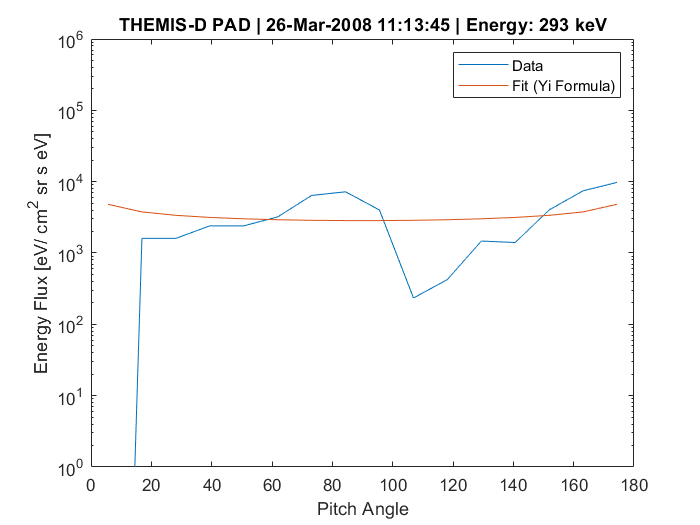

timeStr = '26 Mar 2008 11:13';
energyVal = 300*1000;

pfisr.timeIndex = find_time(pfisr.time,timeStr);
pfisr.energyIndex = find_altitude(pfisr.energyBin,energyVal);

timeIndex = find_time(dataPAD.thd.sst.time,timeStr);
energyIndex1 = find_altitude(dataPAD.thd.sst.energyBin,energyVal);

thm.timeIndex = find_time(thm.time,timeStr);
thm.energyIndex = find_altitude(thm.energyBin,energyVal);

figure; 
semilogy(dataPAD.thd.sst.pa,squeeze(dataPAD.thd.sst.paFlux(timeIndex,energyIndex1,:)));
xlabel('Pitch Angle');
ylabel('Energy Flux [eV/ cm^2 sr s eV]')
title(['THEMIS-D PAD | ',datestr(dataPAD.thd.sst.time(timeIndex)),' | Energy: ',num2str(dataPAD.thd.sst.energyBin(energyIndex1)/1000),' keV']);
ylim([1,10^6]);

timeIndex = find_time(padData.thd.time,timeStr);
energyIndex = find_altitude(padData.thd.energyBin,energyVal);

fun = padData.thd.pitchAngleDistributionFunctionYi;

hold on;
semilogy(padData.thd.pitchAngle,fun(padData.thd.fitYi.x0(timeIndex,energyIndex,:),padData.thd.pitchAngle));
xlabel('Pitch Angle');
ylabel('Energy Flux [eV/ cm^2 sr s eV]')
legend('Data','Fit (Yi Formula)');
ylim([1,10^6]);


% padData.thd.trappedDiffEfluxYi = trapz(convert_deg_to_sr(padData.thd.pitchAngle),squeeze(dataPAD.thd.sst.paFlux(timeIndex,energyIndex1,:))); %fun(padData.thd.fitYi.x0(timeIndex,energyIndex,:),padData.thd.pitchAngle)
padData.thd.trappedDiffEfluxYi = trapz(deg2rad(padData.thd.pitchAngle),squeeze(dataPAD.thd.sst.paFlux(timeIndex,energyIndex1,:)).*2.*pi.*cosd(padData.thd.pitchAngle).*sind(padData.thd.pitchAngle)); 

disp([datestr(thm.time(thm.timeIndex)),' | Energy: ',num2str(dataPAD.thd.sst.energyBin(energyIndex1)/1000),' keV'])

26-Mar-2008 11:13:45 | Energy: 293 keV



%disp(['Loss cone flux from THEMIS                       = ',num2str(padData.thd.lcDiffEfluxLi(timeIndex,energyIndex)),' eV/ cm^2 s eV']);
disp(['Loss cone flux at THEMIS predicted by PFISR      = ', num2str(pfisr.energyFlux(pfisr.energyIndex,1,pfisr.timeIndex).*pi.*(sind(padData.thd.lossConeAngle(timeIndex))).^2),' eV/ cm^2 s eV']);

Loss cone flux at THEMIS predicted by PFISR      = 2.4813 eV/ cm^2 s eV


disp(['Total flux from THEMIS                           = ',num2str(thm.energyFlux(thm.timeIndex,thm.energyIndex).*pi),' eV/ cm^2 s eV']);

Total flux from THEMIS                           = 9446.6925 eV/ cm^2 s eV


disp(' ')

disp('Loss cone flux divided by the total flux:')

Loss cone flux divided by the total flux:


%disp(['THEMIS loss cone flux / THEMIS total flux                         = ', num2str(100*padData.thd.lcDiffEfluxLi(timeIndex,energyIndex)./(thm.energyFlux(thm.timeIndex,thm.energyIndex))),' %']);
disp(['PFISR prediction of loss cone flux / THEMIS total flux            = ', num2str(100*pfisr.energyFlux(pfisr.energyIndex,1,pfisr.timeIndex).*pi.*(sind(padData.thd.lossConeAngle(timeIndex))).^2./(thm.energyFlux(thm.timeIndex,thm.energyIndex).*pi)),' %']);

PFISR prediction of loss cone flux / THEMIS total flux            = 0.026266 %


figure;
energyIndex2 = find_altitude(dataPAD.thd.sst.energyBin,energyVal);
timeIndex2 = find_altitude(dataPAD.thd.sst.time,timeStr);

loglog(dataPAD.thd.sst.energyBin,squeeze(dataPAD.thd.sst.paFlux(timeIndex,:,1)).*10^4,'r');
hold on;
loglog(pfisr.energyBin,squeeze(mean(pfisr.energyFlux(:,:,pfisr.timeIndex),2)*10^4),'k');
xlim([10^3,10^6]);


convert_deg_to_sr(1.6)./convert_deg_to_sr(90)

function [lossConeEnergyFlux,y,MSE] = get_loss_cone_flux(padFun,x0,pa,padData,lcArray,options)
    [y, resnormy] = lsqcurvefit(padFun,x0,pa,padData,[],[],options);
    MSE = resnormy/(length(pa)-2);
    padFunNew = @(x) padFun(y,x);
%     lax=linspace(0,la,50);
%     lossConeEnergyFlux = trapz(convert_deg_to_sr(lcArray),padFunNew(lcArray)); %[eV/cm2 s eV]
    lossConeEnergyFlux = trapz(deg2rad(lcArray),padFunNew(lcArray).*2.*pi.*sind(lcArray)); %[eV/cm2 s eV]
%     lossConeEnergyFlux = integral(padFunNew,0,la); %eV/cm2 s eV
end


function sr = convert_deg_to_sr(angle)
    sr = 4*pi*(sind(angle./2)).^2;
    
end
